exp = input('input the experiment extension: ')

exp = 849

switch exp
    case 757
        cd('/lampllab/Data/Awake_AP2.5_ML4.0_A1/FVB/270721/757')
        load('FVB103_757.mat')
        load('Fvb103 757   27 7 2021 400Fps Whiskers 0-3_proc.mat', 'motion_1')
        motion = motion_1
        clear motion_1
    case 849
        cd('/home/ben/Z/FVB/270721/849')
        load('FVB103_849.mat')
        load('Fvb103 849  27 7 2021 400Fps Whiskers 0-5_proc.mat', 'motion_2')
        motion = motion_2
        clear motion_2
end

motion = 1×716818 single row vector
	1.0e+05 *

    0.1082    0.1299    0.1161    0.0989    0.1134    0.1016    0.1245    0.1131    0.1726    0.1887    0.1785    0.1664    0.1635    0.1666    0.1553    0.1441    0.1453    0.1633    0.1927    0.1955    0.1902    0.1528    0.1358    0.1341    0.1699    0.1862    0.1874    0.1678    0.1626    0.1783    0.1552    0.1621    0.1680    0.1591    0.1634    0.1732    0.1593    0.1821    0.1746    0.1896    0.1650    0.1856    0.1849    0.1875    0.1812    0.1628    0.1720    0.1655    0.1770    0.1745


whiskingStart = experiment.Cams.whsiking.csv_start_frame

whiskingStart = 397

expLength = length(experiment.sound_events.fullSound)

expLength = 53851648

whiskingEnd = find(experiment.Cams.whsiking.csv_aligned_frames < expLength);
whiskingEnd = whiskingEnd(end)

whiskingEnd = 716722

whiskingVector = [whiskingStart:whiskingEnd]

whiskingVector =    397   398   399   400   401   402   403   404   405   406   407   408   409   410   411   412   413   414   415   416   417   418   419   420   421   422   423   424   425   426   427   428   429   430   431   432   433   434   435   436   437   438   439   440   441   442   443   444   445   446


sampleVector = experiment.Cams.whsiking.csv_aligned_frames(whiskingVector)

sampleVector =        74285
       74440
       74488
       74561
       74634
       74709
       74790
       74859
       74939
       75014


whisk_motion = motion(whiskingVector);

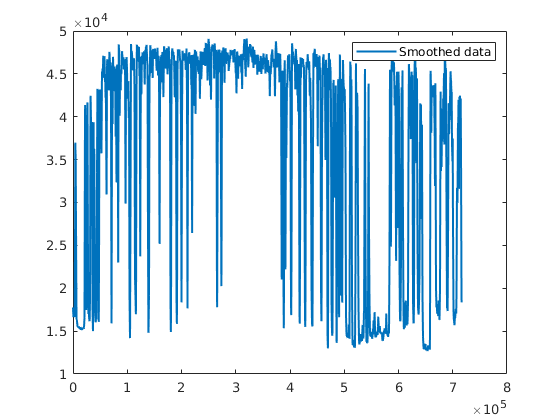

% Smooth input data
Whisk_smooth = smoothdata(whisk_motion,"gaussian",1400);

% Display results
clf
plot(Whisk_smooth,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
legend

Whisk_smooth(Whisk_smooth > 3*10^5) = 3*10^5

Whisk_smooth = 1×716326 single row vector
	1.0e+04 *

    1.7754    1.7752    1.7750    1.7748    1.7746    1.7744    1.7742    1.7740    1.7737    1.7735    1.7733    1.7731    1.7729    1.7727    1.7725    1.7723    1.7720    1.7718    1.7716    1.7714    1.7712    1.7710    1.7707    1.7705    1.7703    1.7701    1.7699    1.7696    1.7694    1.7692    1.7690    1.7688    1.7686    1.7683    1.7681    1.7679    1.7677    1.7674    1.7672    1.7670    1.7669    1.7666    1.7664    1.7662    1.7660    1.7658    1.7657    1.7654    1.7652    1.7650


Whisk_smooth = normalize(Whisk_smooth,"range",[0,1])

Whisk_smooth = 1×716326 single row vector
    0.1395    0.1395    0.1394    0.1393    0.1393    0.1392    0.1392    0.1391    0.1390    0.1390    0.1389    0.1389    0.1388    0.1388    0.1387    0.1386    0.1386    0.1385    0.1385    0.1384    0.1384    0.1383    0.1382    0.1382    0.1381    0.1380    0.1380    0.1379    0.1379    0.1378    0.1377    0.1377    0.1376    0.1376    0.1375    0.1374    0.1374    0.1373    0.1373    0.1372    0.1372    0.1371    0.1370    0.1370    0.1369    0.1369    0.1368    0.1368    0.1367    0.1367


above = find(Whisk_smooth > 0.25)

above =         3593        3594        3595        3596        3597        3598        3599        3600        3601        3602        3603        3604        3605        3606        3607        3608        3609        3610        3611        3612        3613        3614        3615        3616        3617        3618        3619        3620        3621        3622        3623        3624        3625        3626        3627        3628        3629        3630        3631        3632        3633        3634        3635        3636        3637        3638        3639        3640        3641        3642


below = find(Whisk_smooth < 0.25)

below =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


int = intersect(above,below+1)

int =         3593       21487       25095       31493       37366       43899       47914       71427      105784      116417      140203      180869      191909      200346      211376      266095      273690      384811      389017      402710      418409      428659      442034      458528      470454      479001      486639      490940      494011      496483      510195      520709      537045      544030      583353      604523      617955      628749      638758      658336      676788      691075      707095


int_end = intersect(above,below-1)

int_end =         5821       23540       27706       35693       40020       46887       70600      104061      114233      138379      179551      190621      199632      210720      265218      273224      384589      387920      401557      417063      427028      439470      457057      468689      476219      485186      489985      493523      495949      502779      514202      525684      539286      545860      601873      608587      626490      635199      644046      668927      688793      700793      715814


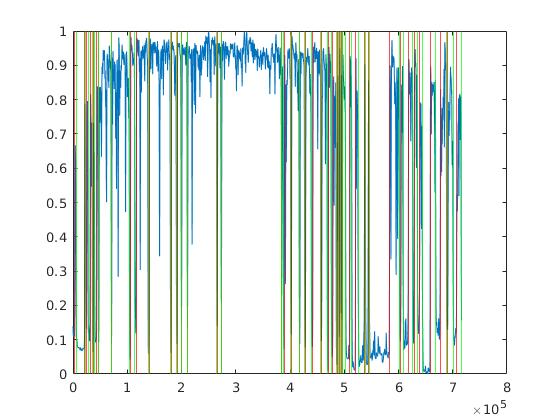

figure;
plot(Whisk_smooth)
hold on

xline(int,'r')
xline(int_end,'g')

int_end(end+1) = length(Whisk_smooth)

int_end =         5821       23540       27706       35693       40020       46887       70600      104061      114233      138379      179551      190621      199632      210720      265218      273224      384589      387920      401557      417063      427028      439470      457057      468689      476219      485186      489985      493523      495949      502779      514202      525684      539286      545860      601873      608587      626490      635199      644046      668927      688793      700793      715814      716326


int_end(1) = [];

Whisking_windows = [sampleVector(int),sampleVector(int_end)]

Whisking_windows =       343896     1840842
     1686773     2153485
     1957536     2752885
     2437696     3077605
     2878433     3592951
     3368706     5386390
     3670024     7897872
     5448453     8661238
     8027178    10473314
     8825141    13563698


relevant_changes = experiment.Conditions.all_changes(1:22)

relevant_changes = 27×1 int64 column vector
    4723592
    6607119
    8496643
   10380171
   12263700
   14141228
   16024759
   17914286
   19791859
   21675390


relevant_changes_class = experiment.Conditions.condition_classification(1:22)

relevant_changes_class =      3
     2
     3
     2
     2
     1
     2
     3
     1
     2


relevant_changes(:,2) = experiment.Conditions.all_changes(2:23)

relevant_changes = 27×2 int64 matrix
    4723592    6607119
    6607119    8496643
    8496643   10380171
   10380171   12263700
   12263700   14141228
   14141228   16024759
   16024759   17914286
   17914286   19791859
   19791859   21675390
   21675390   23564914


audible_times = relevant_changes(relevant_changes_class == 1,:)

audible_times = 11×2 int64 matrix
   14141228   16024759
   19791859   21675390
   25442440   27325965
   29203488   31087011
   32964531   34848095
   36725614   38615130
   42376168   44253686
   44253686   46131205
   46131205   48008724
   48008724   49886286


non_audible_times = relevant_changes(relevant_changes_class == 2,:)

non_audible_times = 9×2 int64 matrix
    6607119    8496643
   10380171   12263700
   12263700   14141228
   16024759   17914286
   21675390   23564914
   27325965   29203488
   31087011   32964531
   34848095   36725614
   40498649   42376168


no_object_times = relevant_changes(relevant_changes_class == 3,:)

no_object_times = 7×2 int64 matrix
    4723592    6607119
    8496643   10380171
   17914286   19791859
   23564914   25442440
   38615130   40498649
   51775804   53665322
   53665322   53851648


audibleTimesVec = expandTimes(audible_times)

audibleTimesVec = 1×20706837 int64 row vector
   14141228   14141229   14141230   14141231   14141232   14141233   14141234   14141235   14141236   14141237   14141238   14141239   14141240   14141241   14141242   14141243   14141244   14141245   14141246   14141247   14141248   14141249   14141250   14141251   14141252   14141253   14141254   14141255   14141256   14141257   14141258   14141259   14141260   14141261   14141262   14141263   14141264   14141265   14141266   14141267   14141268   14141269   14141270   14141271   14141272   14141273   14141274   14141275   14141276   14141277


nonaudibleTimesVec = expandTimes(non_audible_times)

nonaudibleTimesVec = 1×16939722 int64 row vector
   6607119   6607120   6607121   6607122   6607123   6607124   6607125   6607126   6607127   6607128   6607129   6607130   6607131   6607132   6607133   6607134   6607135   6607136   6607137   6607138   6607139   6607140   6607141   6607142   6607143   6607144   6607145   6607146   6607147   6607148   6607149   6607150   6607151   6607152   6607153   6607154   6607155   6607156   6607157   6607158   6607159   6607160   6607161   6607162   6607163   6607164   6607165   6607166   6607167   6607168


noobjectTimesVec = expandTimes(no_object_times)

noobjectTimesVec = 1×11481524 int64 row vector
   4723592   4723593   4723594   4723595   4723596   4723597   4723598   4723599   4723600   4723601   4723602   4723603   4723604   4723605   4723606   4723607   4723608   4723609   4723610   4723611   4723612   4723613   4723614   4723615   4723616   4723617   4723618   4723619   4723620   4723621   4723622   4723623   4723624   4723625   4723626   4723627   4723628   4723629   4723630   4723631   4723632   4723633   4723634   4723635   4723636   4723637   4723638   4723639   4723640   4723641


whiskingVector = expandTimes(Whisking_windows)

whiskingVector =       343896      343897      343898      343899      343900      343901      343902      343903      343904      343905      343906      343907      343908      343909      343910      343911      343912      343913      343914      343915      343916      343917      343918      343919      343920      343921      343922      343923      343924      343925      343926      343927      343928      343929      343930      343931      343932      343933      343934      343935      343936      343937      343938      343939      343940      343941      343942      343943      343944      343945


audibleWhisk = intersect(audibleTimesVec,whiskingVector)

audibleWhisk = 1×20706833 int64 row vector
   14141228   14141229   14141230   14141231   14141232   14141233   14141234   14141235   14141236   14141237   14141238   14141239   14141240   14141241   14141242   14141243   14141244   14141245   14141246   14141247   14141248   14141249   14141250   14141251   14141252   14141253   14141254   14141255   14141256   14141257   14141258   14141259   14141260   14141261   14141262   14141263   14141264   14141265   14141266   14141267   14141268   14141269   14141270   14141271   14141272   14141273   14141274   14141275   14141276   14141277


nonaudibleWhisk = intersect(nonaudibleTimesVec,whiskingVector)

nonaudibleWhisk = 1×16939721 int64 row vector
   6607119   6607120   6607121   6607122   6607123   6607124   6607125   6607126   6607127   6607128   6607129   6607130   6607131   6607132   6607133   6607134   6607135   6607136   6607137   6607138   6607139   6607140   6607141   6607142   6607143   6607144   6607145   6607146   6607147   6607148   6607149   6607150   6607151   6607152   6607153   6607154   6607155   6607156   6607157   6607158   6607159   6607160   6607161   6607162   6607163   6607164   6607165   6607166   6607167   6607168


noObjectWhisk = intersect(noobjectTimesVec,whiskingVector)

noObjectWhisk = 1×11481506 int64 row vector
   4723592   4723593   4723594   4723595   4723596   4723597   4723598   4723599   4723600   4723601   4723602   4723603   4723604   4723605   4723606   4723607   4723608   4723609   4723610   4723611   4723612   4723613   4723614   4723615   4723616   4723617   4723618   4723619   4723620   4723621   4723622   4723623   4723624   4723625   4723626   4723627   4723628   4723629   4723630   4723631   4723632   4723633   4723634   4723635   4723636   4723637   4723638   4723639   4723640   4723641


audibleFR = getfiringRates(experiment.Units,audibleWhisk)

audibleFR =     6.6587    6.1907    3.8074    3.1468    2.0964    9.3462   16.1164   26.1464   24.5499    0.7172   13.7636   11.9888    2.8628    4.8071    5.0867    5.0578    2.1181   14.4271


nonaudibleFR = getfiringRates(experiment.Units,nonaudibleWhisk)

nonaudibleFR =     4.7817    4.8472    3.5933    3.4977    1.1742   10.2097   11.7115   19.7713   28.5270    0.5348   13.3550   13.7871    2.4085    6.9671    3.1559    4.7126    4.1476   13.2009


noobjectFR = getfiringRates(experiment.Units,noObjectWhisk)

noobjectFR =     4.0343    4.3217    2.9264    2.8977    0.8858    6.9242    9.9159   17.8121   25.3503    0.8623   12.8215   12.2963    1.9884    6.3729    3.4752    4.8417    3.5143   13.7778



allFR = [audibleFR;nonaudibleFR;noobjectFR]

allFR =     6.6587    6.1907    3.8074    3.1468    2.0964    9.3462   16.1164   26.1464   24.5499    0.7172   13.7636   11.9888    2.8628    4.8071    5.0867    5.0578    2.1181   14.4271
    4.7817    4.8472    3.5933    3.4977    1.1742   10.2097   11.7115   19.7713   28.5270    0.5348   13.3550   13.7871    2.4085    6.9671    3.1559    4.7126    4.1476   13.2009
    4.0343    4.3217    2.9264    2.8977    0.8858    6.9242    9.9159   17.8121   25.3503    0.8623   12.8215   12.2963    1.9884    6.3729    3.4752    4.8417    3.5143   13.7778


audibleUnitsFR = allFR(:,experiment.evokedEvents.pVal(:,2) == 1)

audibleUnitsFR =     6.6587    6.1907    3.8074    3.1468    9.3462   16.1164   26.1464   24.5499    0.7172   13.7636   11.9888    2.8628    5.0867    5.0578    2.1181
    4.7817    4.8472    3.5933    3.4977   10.2097   11.7115   19.7713   28.5270    0.5348   13.3550   13.7871    2.4085    3.1559    4.7126    4.1476
    4.0343    4.3217    2.9264    2.8977    6.9242    9.9159   17.8121   25.3503    0.8623   12.8215   12.2963    1.9884    3.4752    4.8417    3.5143


function all_times= expandTimes(timesMat)
all_times = [];
for i = 1:length(timesMat)
    tempTimes = timesMat(i,1):timesMat(i,2);
    all_times = [all_times,tempTimes];
end

end

function allUnitsFiring = getfiringRates(unitsStruct,conditionTimes)
allUnitsFiring = zeros(1,(length(unitsStruct.good.id)+length(unitsStruct.mua.id)));
timeInSec = length(conditionTimes)/30000;
for good = 1:length(unitsStruct.good.id)
    spikes = intersect(unitsStruct.good.times(good,:),conditionTimes);
    allUnitsFiring(good) = length(spikes)/timeInSec;  
end
for mua = 1:length(unitsStruct.mua.id)
    spikes = intersect(unitsStruct.mua.times(mua,:),conditionTimes);
    allUnitsFiring(mua+good) = length(spikes)/timeInSec;  
end
end